%% --- 1. Load raw data ---
rgc  = readtable('RGC_coding_raw.csv');
axon = readtable('Axon_coding_raw.csv');
featNames = {'f1','f2','f3'};

%% --- 2. Compute joint std per feature ---
% Stack RGC and axon feature columns, then compute std along each column.
combined = [rgc{:, featNames}; axon{:, featNames}];   % (n_rgc + n_axon) x 3
scale    = std(combined, 1);                          % 1x3 ; 1 = population std (N)
                                                      % use std(combined,0) for sample std (N-1) if you prefer
 
fprintf('Scale factors (joint std per feature):\n');
for j = 1:numel(featNames)
    fprintf('  %s : divide by %.4f\n', featNames{j}, scale(j));
end

%% --- 3. Apply scaling to each dataset ---
rgc_scaled  = rgc;
axon_scaled = axon;
for j = 1:numel(featNames)
    rgc_scaled.(featNames{j})  = rgc.(featNames{j})  / scale(j);
    axon_scaled.(featNames{j}) = axon.(featNames{j}) / scale(j);
end

function s = ternary(cond, a, b)
    if cond, s = a; else, s = b; end
end
%% --- 4. Sanity checks ---
fprintf('\nAfter scaling -- spans (max-min) per feature:\n');
fprintf('  %-8s %-12s %-12s\n', 'feature', 'RGC span', 'axon span');
for j = 1:numel(featNames)
    fprintf('  %-8s %-12.3f %-12.3f\n', featNames{j}, ...
        max(rgc_scaled.(featNames{j}))  - min(rgc_scaled.(featNames{j})), ...
        max(axon_scaled.(featNames{j})) - min(axon_scaled.(featNames{j})) );
end
 
fprintf('\nRelative relationships preserved? (mean comparison)\n');
for j = 1:numel(featNames)
    raw_bigger    = mean(rgc.(featNames{j}))        > mean(axon.(featNames{j}));
    scaled_bigger = mean(rgc_scaled.(featNames{j})) > mean(axon_scaled.(featNames{j}));
    fprintf('  %s : raw RGC>axon = %d, scaled RGC>axon = %d, preserved = %s\n', ...
        featNames{j}, raw_bigger, scaled_bigger, ...
        ternary(raw_bigger == scaled_bigger, 'yes', 'NO'));
end

%% --- 5. Save scaled data ---
writetable(rgc_scaled,  'RGC_coding_scaled.csv');
writetable(axon_scaled, 'Axon_coding_scaled.csv');
 
fprintf('\nWrote: RGC_coding_scaled.csv\n');
fprintf('Wrote: Axon_coding_scaled.csv\n');

fig = figure;
clf(fig);
hold on;
scatter3(rgc_scaled.f1, rgc_scaled.f2, rgc_scaled.f3, 'filled');
scatter3(axon_scaled.f1, axon_scaled.f2, axon_scaled.f3, 'filled');
grid on;
hold off;

%t = readtable('Axon_joint_zscore.csv')
t= readtable('Axon_coding.csv');
repre2 = table2array(t);
repre2 = repre2(:, 2:4);

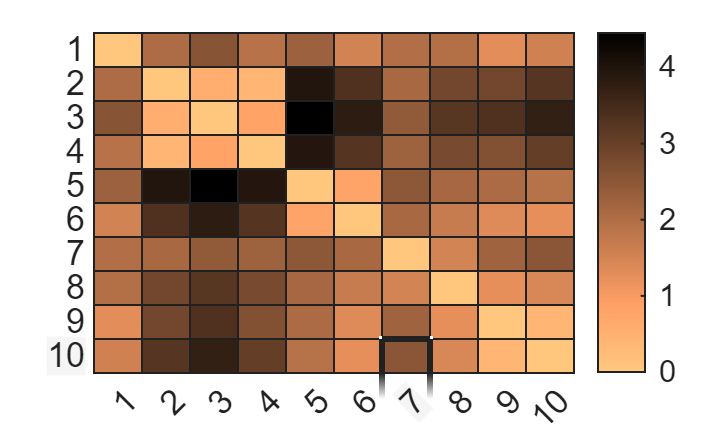

r_repre2 = flipud(repre2);
dist = zeros([height(repre2) height(repre2)]);
for i = 1:height(repre2)
    for j = 1:height(repre2)
        dist(i, j) = norm(r_repre2(i, :)- r_repre2(j, :));
    end
end
h = heatmap(dist);
h.Colormap = flipud(copper);
% axs = struct(h);
% cb = axs.Colorbar;
% cb.Ticks = [];
% h.XDisplayLabels = repmat({''}, 1, size(dist, 2));
% h.YDisplayLabels = repmat({''}, size(dist, 1), 1);
h.CellLabelColor = 'none';
saveas(gcf, 'axon_dist_heat.svg');

t = readtable('RGC_coding_scaled.csv');
repre3 = table2array(t);
repre3 = repre3(:, 2:4);
axon_grouping = {[1,2], [5,6], [7, 8, 9]};
mean_axons = zeros([numel(axon_grouping), 3]);
for i = 1:numel(axon_grouping)
    indx = axon_grouping{i};
    mean_axons(i, :) = mean(repre2(indx, :), 1);
end
sorted_axons = [mean_axons(1, :);
    repre2(3, :);
    repre2(4, :);
    mean_axons(3, :);
    repre2(10, :)];

sorted_rgcs = [repre3(4, :);
    repre3(2, :);
    repre3(3, :);
    repre3(1, :);
    repre3(5, :)];

num_fit = height(sorted_rgcs);
R_aug = [transpose(sorted_rgcs); ones(1,num_fit)];
A_aug = transpose(sorted_axons) / R_aug; 
A = A_aug(:, 1:3);   
b = A_aug(:, 4);     

%prediction_input = A * transpose(repre3) + b;
prediction_input = A * transpose(sorted_rgcs) +b;
a_predicted = transpose(prediction_input);

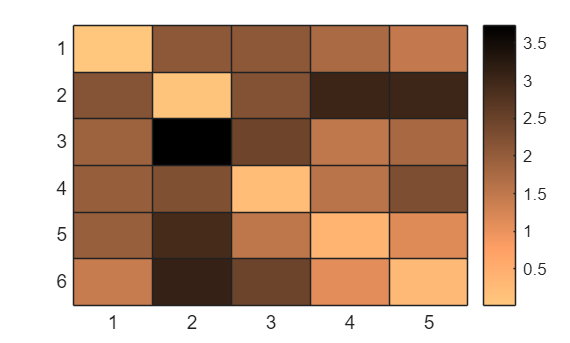

%distance between centroid of axon and rgc predicted
sorted_axons_r = [mean_axons(1, :);
    repre2(3, :);
    repre2(4, :);
    mean_axons(2, :);
    mean_axons(3, :);
    repre2(10, :)];
sorted_axons_r = flipud(sorted_axons_r);
a_predicted = flipud(a_predicted);
dist_pre = zeros([height(sorted_axons_r), height(a_predicted)]);
for i = 1:height(sorted_axons)
    for j = 1:height(repre3)
        dist_pre(i, j) = norm(sorted_axons_r(i, :) - a_predicted(j, :));
    end
end
%  copyd = dist_pre;
% dist_pre(:, 1) = copyd(:, 5);
% dist_pre(:, 2) = copyd(:, 1);
h = heatmap(dist_pre);
h.Colormap = flipud(copper);
h.CellLabelColor = 'none';
saveas(gcf, 'prediction_dist_heat.svg');

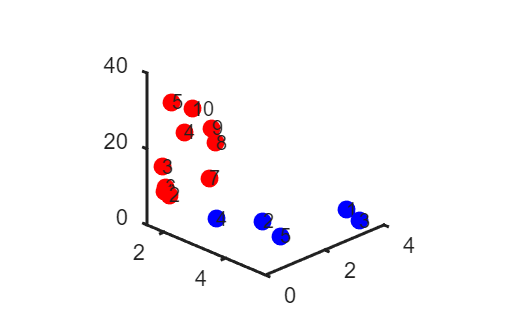

%plot this
fig = figure;
clf(fig);

ax = axes(fig);
hold(ax, 'on');
scatter3(ax, repre3(:, 1), repre3(:, 2), repre3(:, 3), 80, 'blue', 'filled');
X = [repre3(:,1)'; a_predicted(:,1)'];   % 2 x 5
Y = [repre3(:,2)'; a_predicted(:,2)'];   % 2 x 5
Z = [repre3(:,3)'; a_predicted(:,3)'];   % 2 x 5
%plot3(ax, X, Y, Z, '--', 'Color','black', 'LineWidth', 1.2);
scatter3(ax, repre2(:, 1), repre2(:, 2), repre2(:, 3), 80, 'red', 'filled');
for j = 1:height(repre2)
    text(ax, repre2(j, 1),repre2(j, 2), repre2(j, 3), ...
        num2str(j));
end
% scatter3(ax, a_predicted(:, 1),a_predicted(:, 2), a_predicted(:, 3), 80, 'green', 'filled');
for i = 1:height(repre3)
    text(ax, repre3(i, 1), repre3(i, 2), repre3(i, 3),...
        num2str(i));
end
labels = {'rgc', 'axon', 'prediction axon'};
view(45, 25);
set(ax, 'FontSize', 11, 'LineWidth', 1.5);
%legend(labels);
%title('Affine transformation');
% xlabel('color representation 1');
% ylabel('color representation 2');
% view(ax, 25, 45);
% zticks(ax, [-1, 0, 1, 2, 3, 4]);
% xticks(ax, linspace(-2, 4,7));
% yticks(ax, linspace(-1, 3, 5));
%axis(ax, 'equal');
pbaspect(ax,[1, 1, 1]);

hold(ax, 'off');